# Classify Human Electrocardiogram (ECG) Signals

#### Gajiyev Timur

## **Electrocardiogram (ECG) - **

The ECG signal reflects the electrical activity of the heart observed from the strategic points of the human body and represented by quasi-periodic voltage signal.

Also known as an electrocardiogram or an EKG, an ECG is a test that detects and records the strength and timing of the electrical activity in your heart. This information is recorded on a graph that shows each phase of the electrical signal as it travels through your heart.

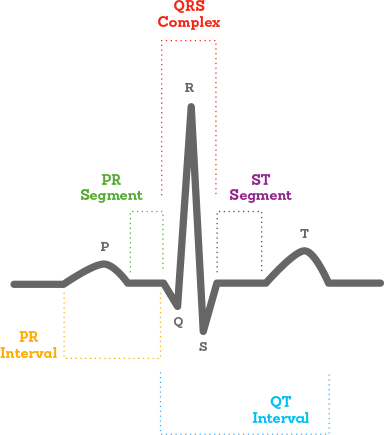

This signal is recorded as the QRS waves on the ECG. Because these waves occur in rapid succession they are usually considered together as the QRS complex.

The ventricles then recover to their normal electrical state, shown as the T wave. The muscles relax and stop contracting, allowing the atria to fill with blood and the entire process repeats with each heartbeat. The ST segment connects the QRS complex and the T wave and represents the beginning of the electrical recovery of the ventricles.

The QT interval represents the time during which the ventricles are stimulated and recover after the stimulation. This interval shortens at a faster heart rate and lengthens at a slower heart rate.

In general people can be devided in three groups:

- persons with cardiac arrhythmia (ARR)

- persons with congestive heart failure (CHF), and

- persons with normal sinus rhythms (NSR). 

The goal of this PStA is to classify human electrocardiogram (ECG) signals using the Short Time Fourier Transformation and the Continuous Wavelet Transform (CWT) and deep convolutional neural networks (CNNs). The resulting CNNs shall be used to classify the given ECG signal to ARR, CHF, and NSR, respectively. 

### Matlab Example

The Matlab Example [Classify Time Series Using Wavelet Analysis and Deep Learning - MATLAB & Simulink Example - MathWorks Deutschland](https://de.mathworks.com/help/releases/R2020b/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html) can be taken as a basis. It uses ECG data (the training and test data are publicly available from [PhysioNet](https://physionet.org/)) obtained from three groups of people: persons with cardiac arrhythmia (ARR), persons with congestive heart failure (CHF), and persons with normal sinus rhythms (NSR). In total  162 ECG recordings from three PhysioNet databases are used: [MIT-BIH Arrhythmia Database](https://www.physionet.org/physiobank/database/mitdb/) , [MIT-BIH Normal Sinus Rhythm Database](https://www.physionet.org/physiobank/database/nsrdb/) , and [The BIDMC Congestive Heart Failure Database](https://www.physionet.org/physiobank/database/chfdb/); more specifically, 96 recordings from persons with arrhythmia, 30 recordings from persons with congestive heart failure, and 36 recordings from persons with normal sinus rhythms. Two deep CNNs, GoogLeNet and SqueezeNet, pretrained for image recognition, are adapted to classify ECG waveforms based on a time-frequency representation -- the Wavelet Transformation.

Given is the following ECG signal. The ECG signal is sampled at 8 kHz and resampled to 128 Hz for compitability.

**Load ecg signal**

% clear all
ecg = load('ecg.mat');


**Resample the given ECG signal to be compitable with PhysioNet database**

ecg.data = resample(ecg.data,2,125);
ecg.fs = 128;


**Graphical Output with Time Signal**

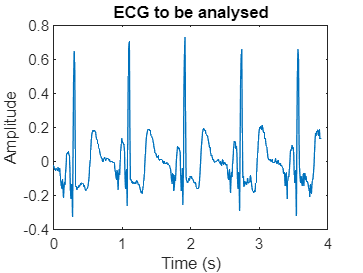

time= [0 : length(ecg.data) - 1] / ecg.fs;
plot(t(1:500), ecg.data(1:500))
title('ECG to be analysed')
xlabel('Time (s)')
ylabel('Amplitude')

** Short Time Fourier Analysis** -- Spectrogram

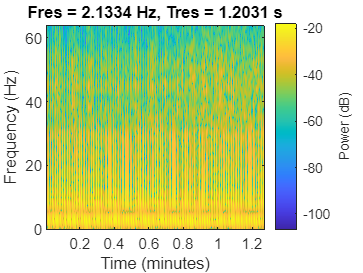

pspectrum(ecg.data,ecg.fs, 'spectrogram')

**Wavelet Analysis** -- Scalogram

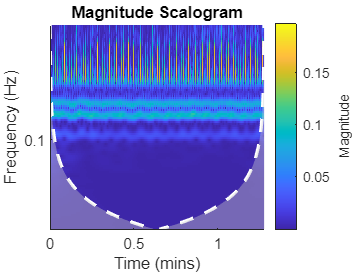

cwt(ecg.data, [], ecg.fs)

## Data Preprocessing & Datastore

Generate the time-frequency representation using

- Short Time Fourier Transformation and

- Wavelet Transformation

and generate the corresponding data stores.

Compare the impact on the CNNs by comparing the confusion charts!

The complete PhysioNet has been downloaded and is present under the MATLB data container under the name "ECGData.mat". 

GenerateData = 1;

** The working WaveletDirectory name**

WaveletDirectory = "ECGTypesWavelet";  % The working Directory name
STFTDirectory = 'ECGTypesSTFT';

  **Load PhysioNet data**

load('ECGData.mat');  
ECGRawData = ECGData.Data;   % Datasets ECG timeseries
ECGLabels = ECGData.Labels;  % Datasets ECG labels (i.e. ARR, CHF, and NSR)
fs = 128;                    % Sampling frequency for ECGs in PhysioNet database
clear ECGData                % Clear the workspace variable

**Plot different available ECGs from PhysioNet to be used in training phase and seperate the unique ECG types (i.e. ARR, CHF, and NSR)**

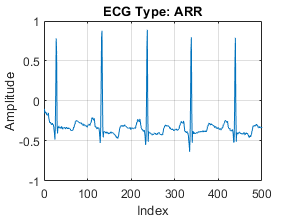

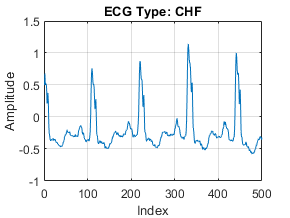

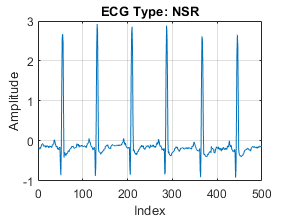

ECGTypes = unique(ECGLabels);  
for i=1:length(ECGTypes)  % For every ECG types (i.e. 3)
    ECG = ECGTypes{i};    % Get the ECG type
    index = find(ismember(ECGLabels,ECG));  % Find a corresponding timeseries
    index = index(1);     % Index of the first timeseries
    figure()              % Generte a figure
    plot(ECGRawData(index, 1 : 500));  %  Plot the first 500 samples of that unique ECG
    grid on
    xlabel('Index')
    ylabel('Amplitude')
    title(['ECG Type: ' ECG])
end

**Evaluate one of the training ECG signals**

if GenerateData == 1  % 1: Generate data for training from PhysioNet, 0: Use existing data

**Evaluate one sample (Data Preprocessing)**

    FilterBank = cwtfilterbank('SignalLength', 1000, 'SamplingFrequency', fs, 'VoicesPerOctave', 12);  % Design a filter bank for the first 1000 samples at the sampling rate
    Signal = ECGRawData(1,1:1000);  % Portion of one ECG signal from PhysioNet dataset

    % Generte Wavelet Transformation Coefficients and frequencies with filter bank
    [cfs,frq] = wt(FilterBank,Signal);
    % Plot the spectrogram for the sample
    time= (0:999)/fs;          % time axis

Number of training images: 130


    figure();                % Generte new figure

Number of validation images: 32


    pcolor(t,frq,abs(cfs))   % Create a pseudocolor based on generated coefficients (Scalogram)
    set(gca,'yscale','log'); % Set logarithmic y-axis
    shading interp;          % Set color shading property to colour interpolation
    axis tight;
    title('Scalogram (Example for one PhysioNet ECG)');
    xlabel('Time (s)');
    ylabel('Frequency (Hz)') 

**Generate RGB images (scalograms) of all the ECG signals in the PhysioNet database**

Generate data for training

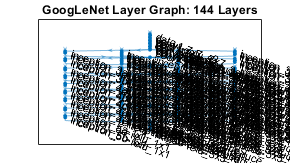

    [~,SignalLength] = size(ECGRawData);  % Get the length of the ECG signals
    FilterBank = cwtfilterbank('SignalLength',SignalLength,'SamplingFrequency',fs,'VoicesPerOctave',12);  % Filter bank
    
    % Generate scalograms as RGB images (jpg) for every ECG in PhysioNet library
    r = size(ECGRawData,1);  % Number of the PhysioNet ECG signals
    for i = 1:r
        cfs = abs(FilterBank.wt(ECGRawData(i,:))); 
        im = ind2rgb(im2uint8(rescale(cfs)),jet(128));
        imgLoc = fullfile(WaveletDirectory,char(ECGLabels(i)));
        imFileName = strcat(char(ECGLabels(i)),'_',num2str(i),'.jpg');
        imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));  % Set image size of 224x224x3 for GoogLeNet training
    end


    % STFM
    L = 32;                            
    dN = 0.75*L;                    
    N = 2*L;                            
    Window = gausswin(L);  
    Overlap = round(L-dN);  

    STFTDirectory = "ECGTypeSTFT";  % The working directory name
    for i = 1:r
        [spectrum,f,t] = stft(ECGRawData(i,:),fs,'Window',Window,"OverlapLength",Overlap,"FFTLength",N);

        spectrum = abs(spectrum);

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


        im = ind2rgb(im2uint8(rescale(spectrum)),jet(128));
        imgLoc = fullfile(STFTDirectory,char(ECGLabels(i)));
        imFileName = strcat(char(ECGLabels(i)),'_',num2str(i),'.jpg');
        imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));  % Set image size of 224x224x3 for GoogLeNet training
    end


else
    % Do nothing here
end

**Generate datastore for training the model**

Store the generated images in a image datastore

% Images = imageDatastore(fullfile(WaveletDirectory),'IncludeSubfolders',true,'LabelSource','foldernames');
Images = imageDatastore(fullfile(STFTDirectory),'IncludeSubfolders',true,'LabelSource','foldernames');


rng default  % Set default random number generator

[TrainingImages,ValidationImages] = splitEachLabel(Images,0.8);  % Split the images into training and vlidation sets
disp(['Number of training images: ',num2str(numel(TrainingImages.Files))]);
disp(['Number of validation images: ',num2str(numel(ValidationImages.Files))]);

% Rescale (227x227) training and validation images datastore to be used in SqueezeNetand AlexNet
RescaledTrainingImages = augmentedImageDatastore([227 227],TrainingImages);
RescaledValidationImages = augmentedImageDatastore([227 227],ValidationImages);

**Generate scalogram for the given ECG signal for classification/prediction**

Generte Scalogram for the given ECG signal

GenerateECGScalogram = 1;               % 0: Load existing RGB image for the given ECG signal, 1: Generate a new one

if GenerateECGScalogram == 1
    % Generte data for training

Number of Layers: 68


    [SignalLength,~] = size(ecg.data);

   227   227     3



    FilterBank = cwtfilterbank('SignalLength',SignalLength,'SamplingFrequency',fs,'VoicesPerOctave',12);  % Filter bank
    
    cfs = abs(FilterBank.wt(ecg.data));                    % Get Wavelet transform coefficient for the given ECG signal
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));         % Convert indexed image with the corresponding colourmap to RGB image

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            Convolution                  1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes


%     imFileName = strcat('ECG_To_Evaluate','.jpg');         % RGB image filename
    imFileName = strcat('ECG_To_EvaluateSTFT','.jpg');         % RGB image filename
    imwrite(imresize(im,[224 224]),fullfile(imFileName));  % Write to image with 224x224 size to be compitable with GoogLeNet
else
    % Do nothing here
end

## Design CNNs

For the CNNs the following pretrained networks shall be used: GooLeNet, SqueezeNet and AlexNet. Adopt the networks to the ECG classification.

### GoogLeNet

GoogLeNet = googlenet;  % Use GoogLeNet model

**Graph of network layers**

GoogLeNetLayerGraph = layerGraph(GoogLeNet);  
NumberOfLayers = numel(GoogLeNetLayerGraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(GoogLeNetLayerGraph)
title(['GoogLeNet Layer Graph: ',num2str(NumberOfLayers),' Layers']);
GoogLeNet.Layers(1)
NewDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                      60% dropout
     2   'new_conv'          Convolution                  3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                         ReLU
     4   'pool10'            2-D Global Average Pooling   2-D global average pooling
     5   'prob'              Softmax                      softmax
     6   'new_classoutput'   Classification Output        crossentropyex

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       20.00% |       28.12% |       2.6861 |       1.6527 |      1.0000e-04 |
|       2 |          10 |       00:00:26 |       73.33% |       59.38% |       1.2450 |       1.2015 |      1.0000e-04 |
|       3 |          20 |       00:00:44 |       46.67% |       59.38% |       1.0532 |       0.8190 |      1.0000e-04 |
|       4 |          30 |       00:01:01 |       60.00% |       62.50% |       0.8954 |       0.6515 |      1.0000

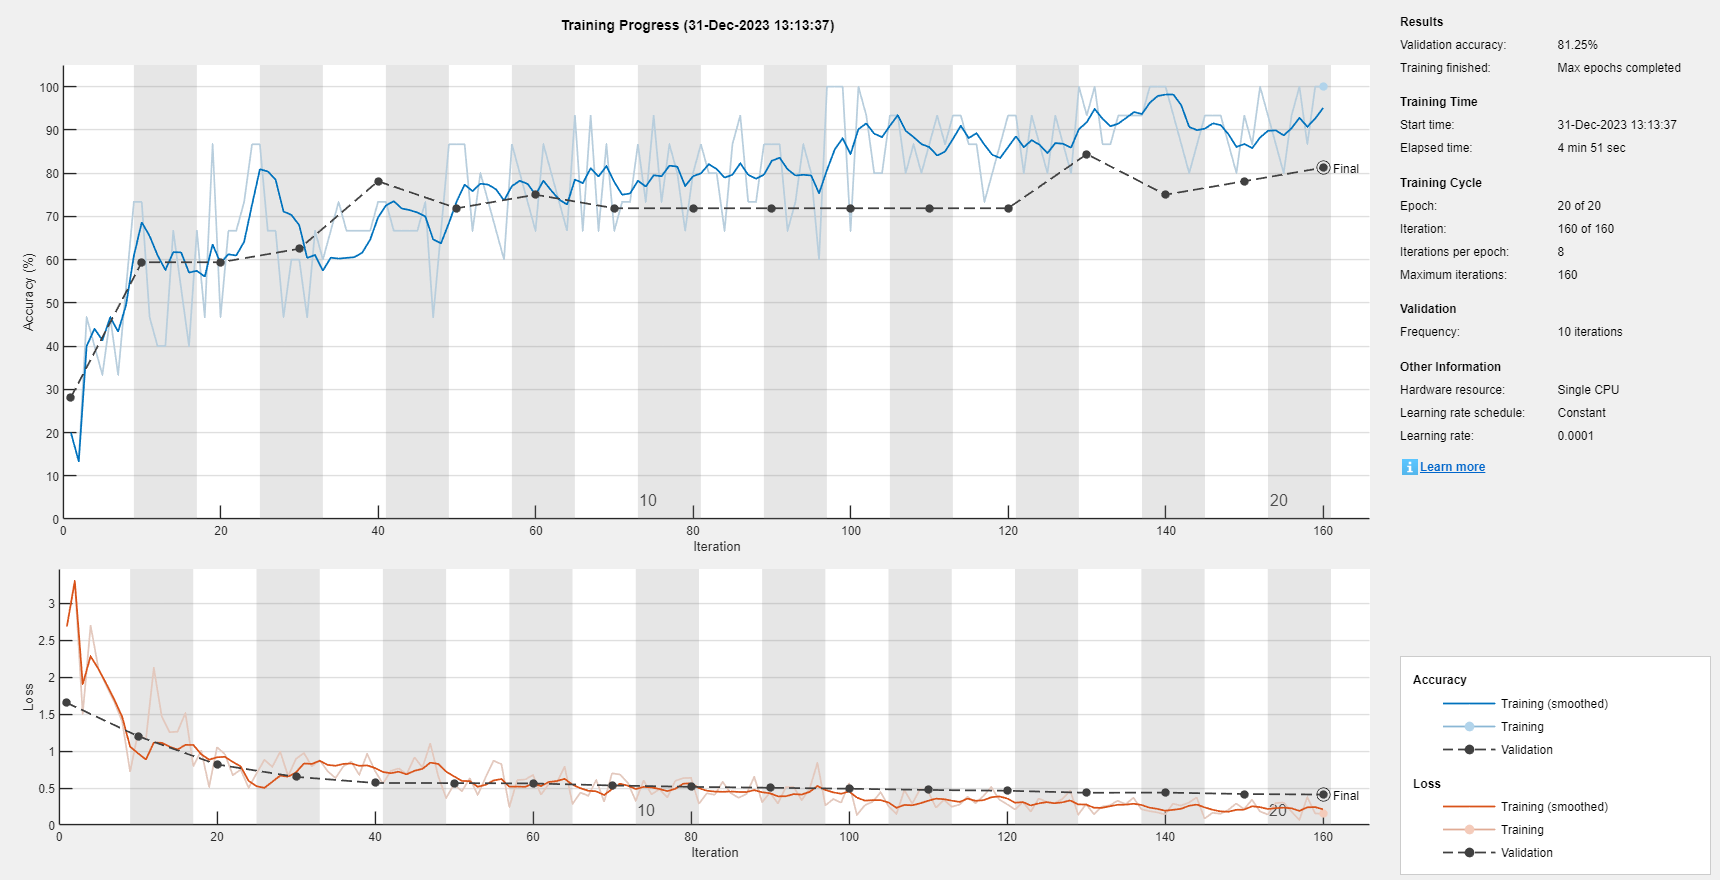

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       50.00% |       59.38% |       1.3185 |       0.9129 |          0.0003 |
|       1 |          13 |       00:00:11 |       90.00% |       59.38% |       0.7708 |       1.0292 |          0.0003 |
|       2 |          26 |       00:00:19 |       90.00% |       71.88% |       0.4256 |       0.8571 |          0.0003 |
|       3 |          39 |       00:00:28 |       70.00% |       68.75% |       0.5187 |       0.7201 |          0.

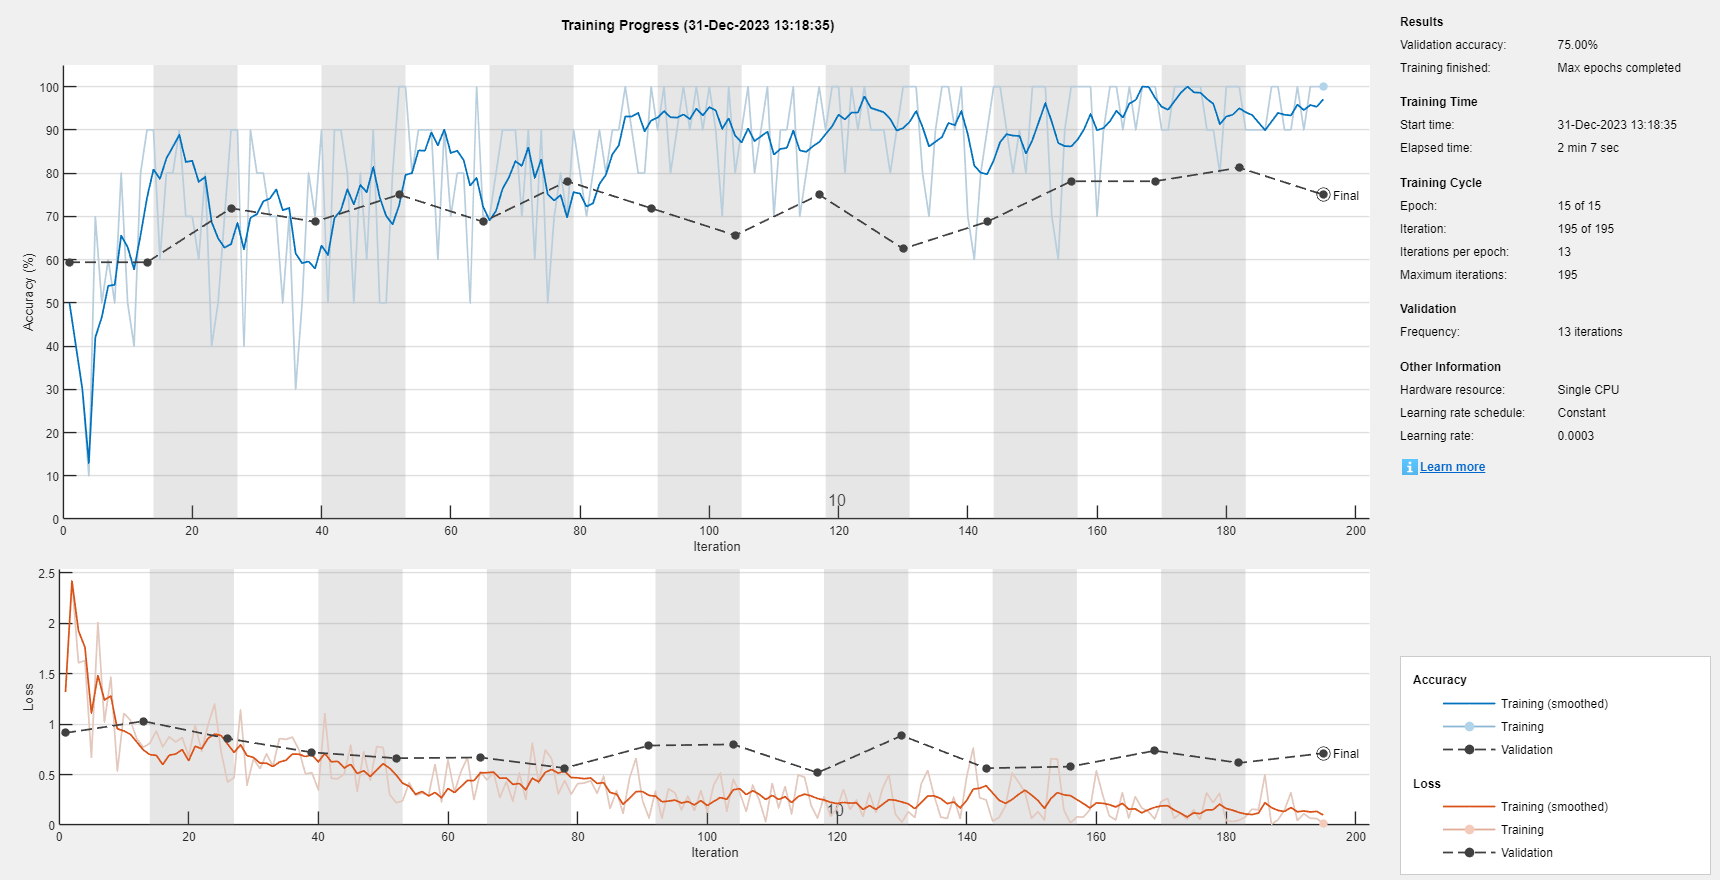

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       40.00% |       53.12% |       1.6926 |       1.2881 |      1.0000e-04 |
|       1 |          13 |       00:00:11 |       70.00% |       68.75% |       2.2526 |       1.0078 |      1.0000e-04 |
|       2 |          26 |       00:00:12 |       60.00% |       68.75% |       1.4124 |       0.6044 |      1.0000e-04 |
|       3 |          39 |       00:00:14 |       70.00% |       90.62% |       0.6288 |   

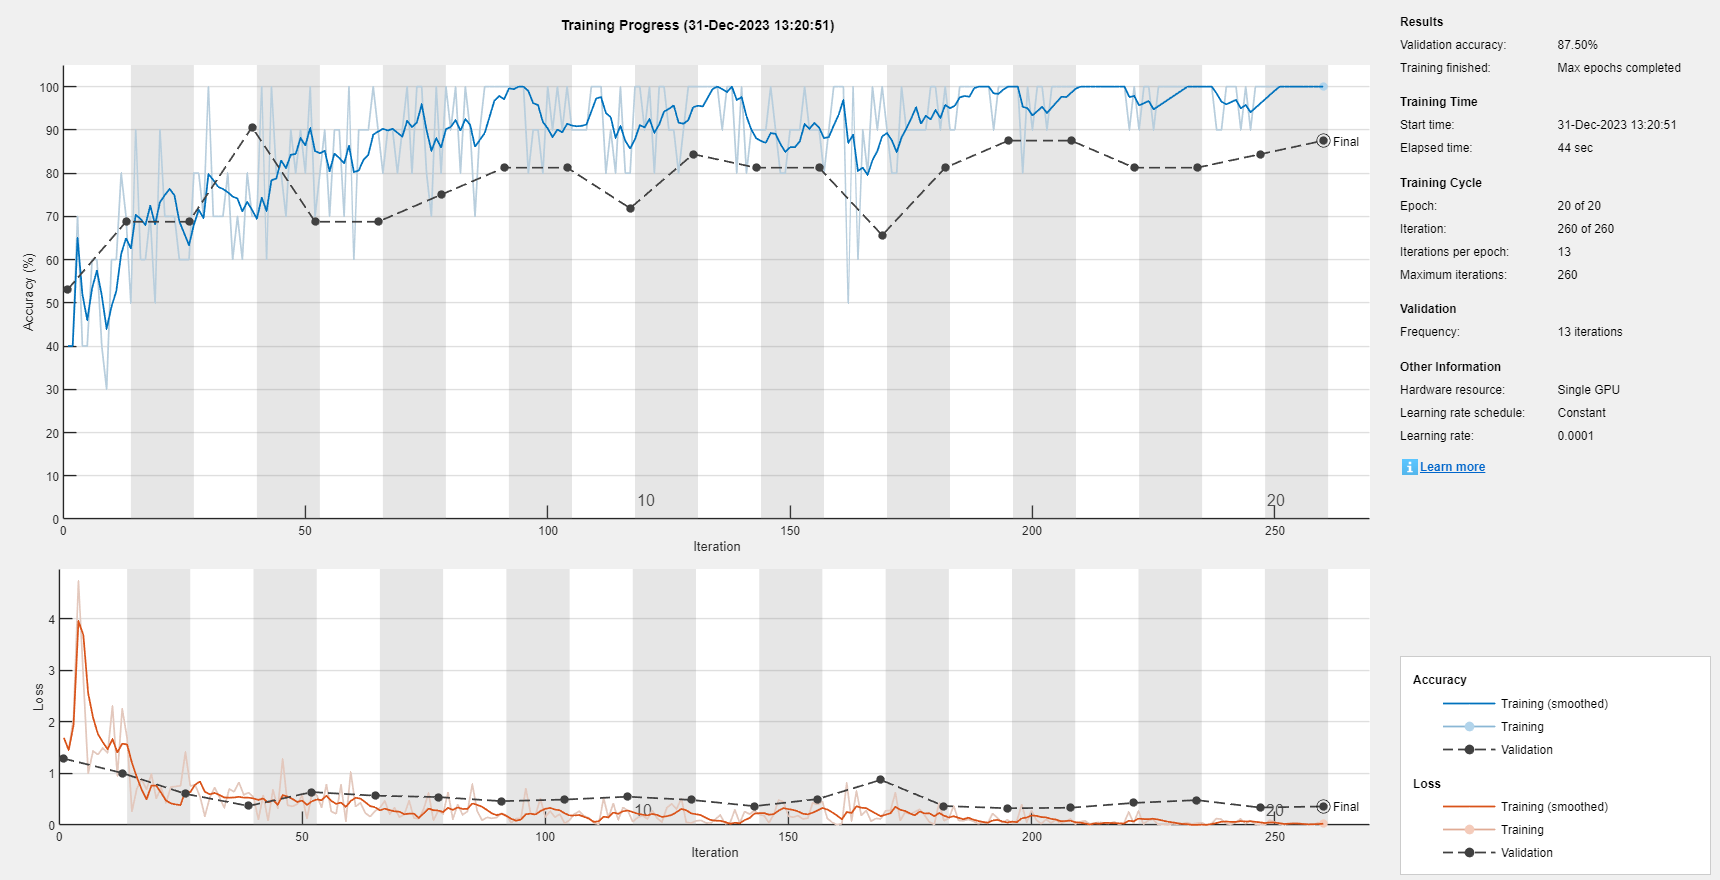

ans =   ClassificationOutputLayer with properties:

            Name: 'classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


GoogLeNetLayerGraph = replaceLayer(GoogLeNetLayerGraph,'pool5-drop_7x7_s1',NewDropoutLayer);

NumClasses = numel(categories(TrainingImages.Labels));
NewConnectedLayer = fullyConnectedLayer(NumClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
GoogLeNetLayerGraph = replaceLayer(GoogLeNetLayerGraph,'loss3-classifier',NewConnectedLayer);

NewClassLayer = classificationLayer('Name','new_classoutput');
GoogLeNetLayerGraph = replaceLayer(GoogLeNetLayerGraph,'output',NewClassLayer);

GoogLeNetOptions = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',ValidationImages,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
 

% [PredictedLabel,Probability] = classify(GoogLeNetTrained,imgsValidation);
% accuracy = mean(PredictedLabel==imgsValidation.Labels);
% disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])
% 
% wghts = GoogLeNetTrained.Layers(2).Weights;
% wghts = rescale(wghts);
% wghts = imresize(wghts,5);
% figure
% montage(wghts)
% title('First Convolutional Layer Weights')
% 
% convLayer = 'conv1-7x7_s2';
% 
% imgClass = 'ARR';
% imgName = 'ARR_10.jpg';
% imarr = imread(fullfile(WaveletDirectory,imgClass,imgName));
% 
% trainingFeaturesARR = activations(GoogLeNetTrained,imarr,convLayer);
% sz = size(trainingFeaturesARR);
% trainingFeaturesARR = reshape(trainingFeaturesARR,[sz(1) sz(2) 1 sz(3)]);
% figure
% montage(rescale(trainingFeaturesARR),'Size',[8 8])
% title([imgClass,' Activations'])
% 
% imgSize = size(imarr);
% imgSize = imgSize(1:2);
% [~,maxValueIndex] = max(max(max(trainingFeaturesARR)));
% arrMax = trainingFeaturesARR(:,:,:,maxValueIndex);
% arrMax = rescale(arrMax);
% arrMax = imresize(arrMax,imgSize);
% figure;
% imshowpair(imarr,arrMax,'montage')
% title(['Strongest ',imgClass,' Channel: ',num2str(maxValueIndex)])

### SqueezeNet

SqueezeNet is a deep CNN whose architecture supports images of size 227-by-227-by-3. Even though the image dimensions are different for GoogLeNet, you do not have to generate new RGB images at the SqueezeNet dimensions. You can use the original RGB images.

SqueezeNet = squeezenet;

SqueezeNetLayerGraph = layerGraph(SqueezeNet);

GoogLeNet Accuracy: 81.25%


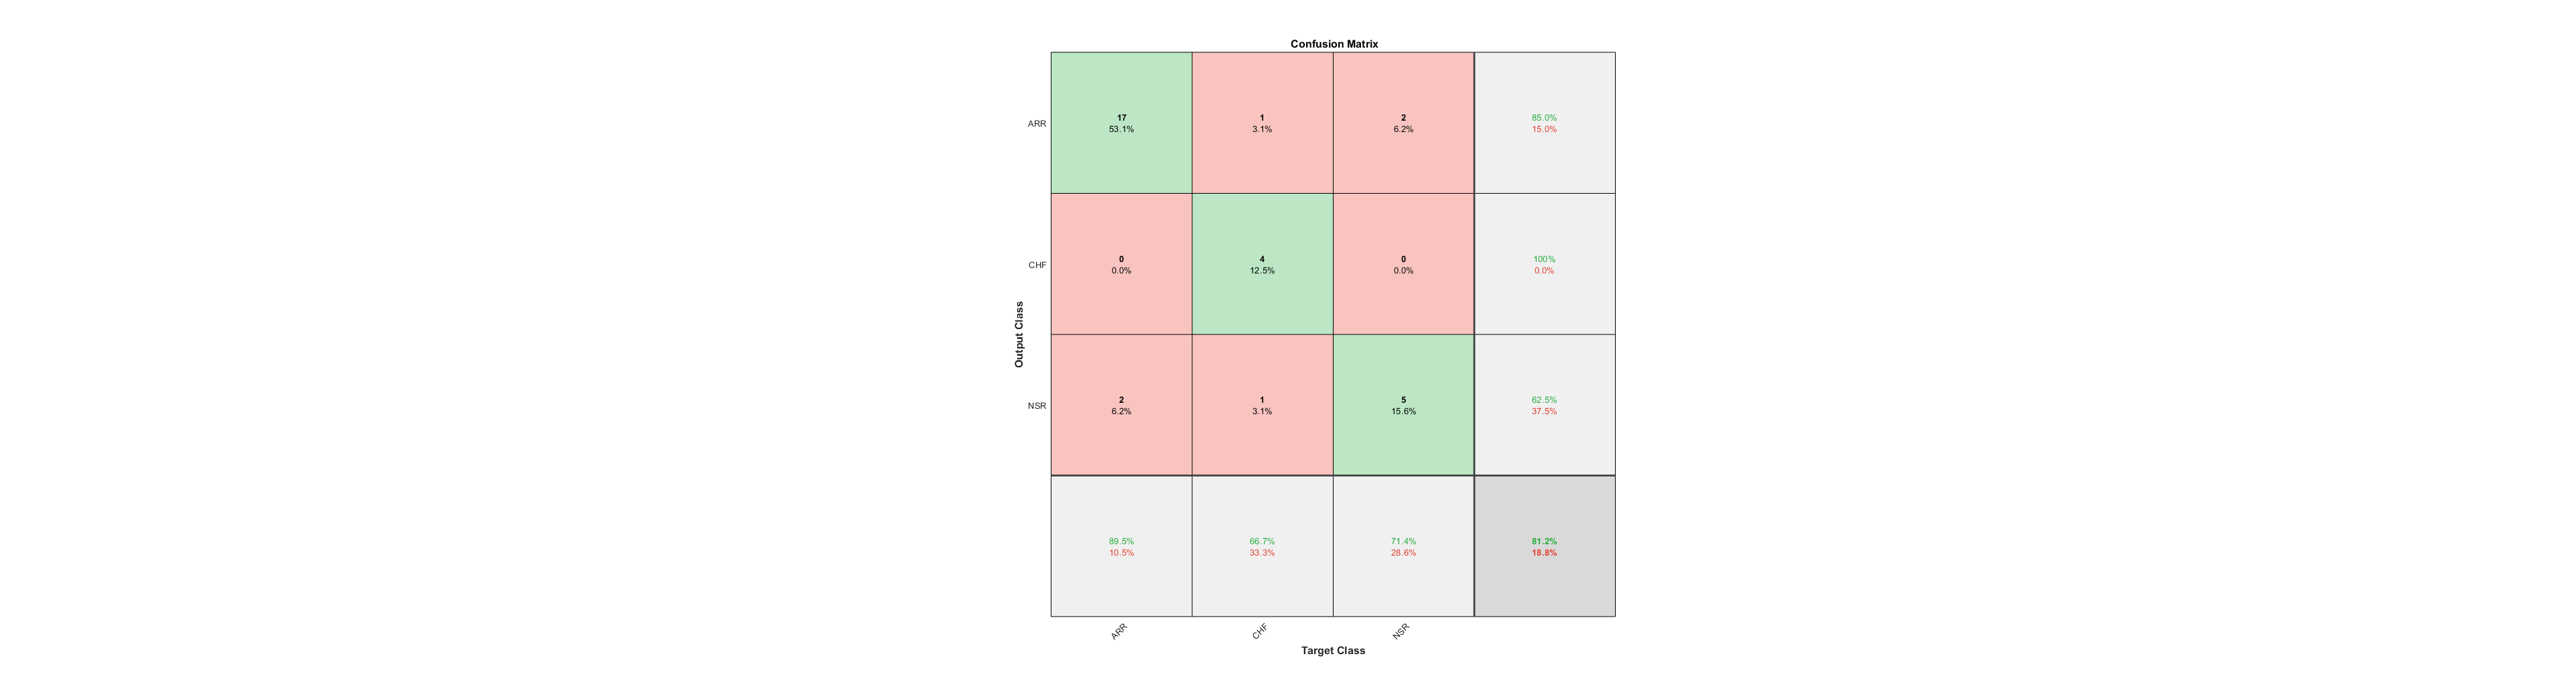

disp(['Number of Layers: ',num2str(numel(SqueezeNetLayerGraph.Layers))])

disp(SqueezeNetLayerGraph.Layers(1).InputSize)

**Modify SqueezeNet Network Parameters**

To retrain SqueezeNet to classify new images, make changes similar to those made for GoogLeNet.

Inspect the layers.

SqueezeNetLayerGraph.Layers(end-5:end)

tmpLayer = SqueezeNetLayerGraph.Layers(end-5);

SqueezeNet Accuracy: 75%


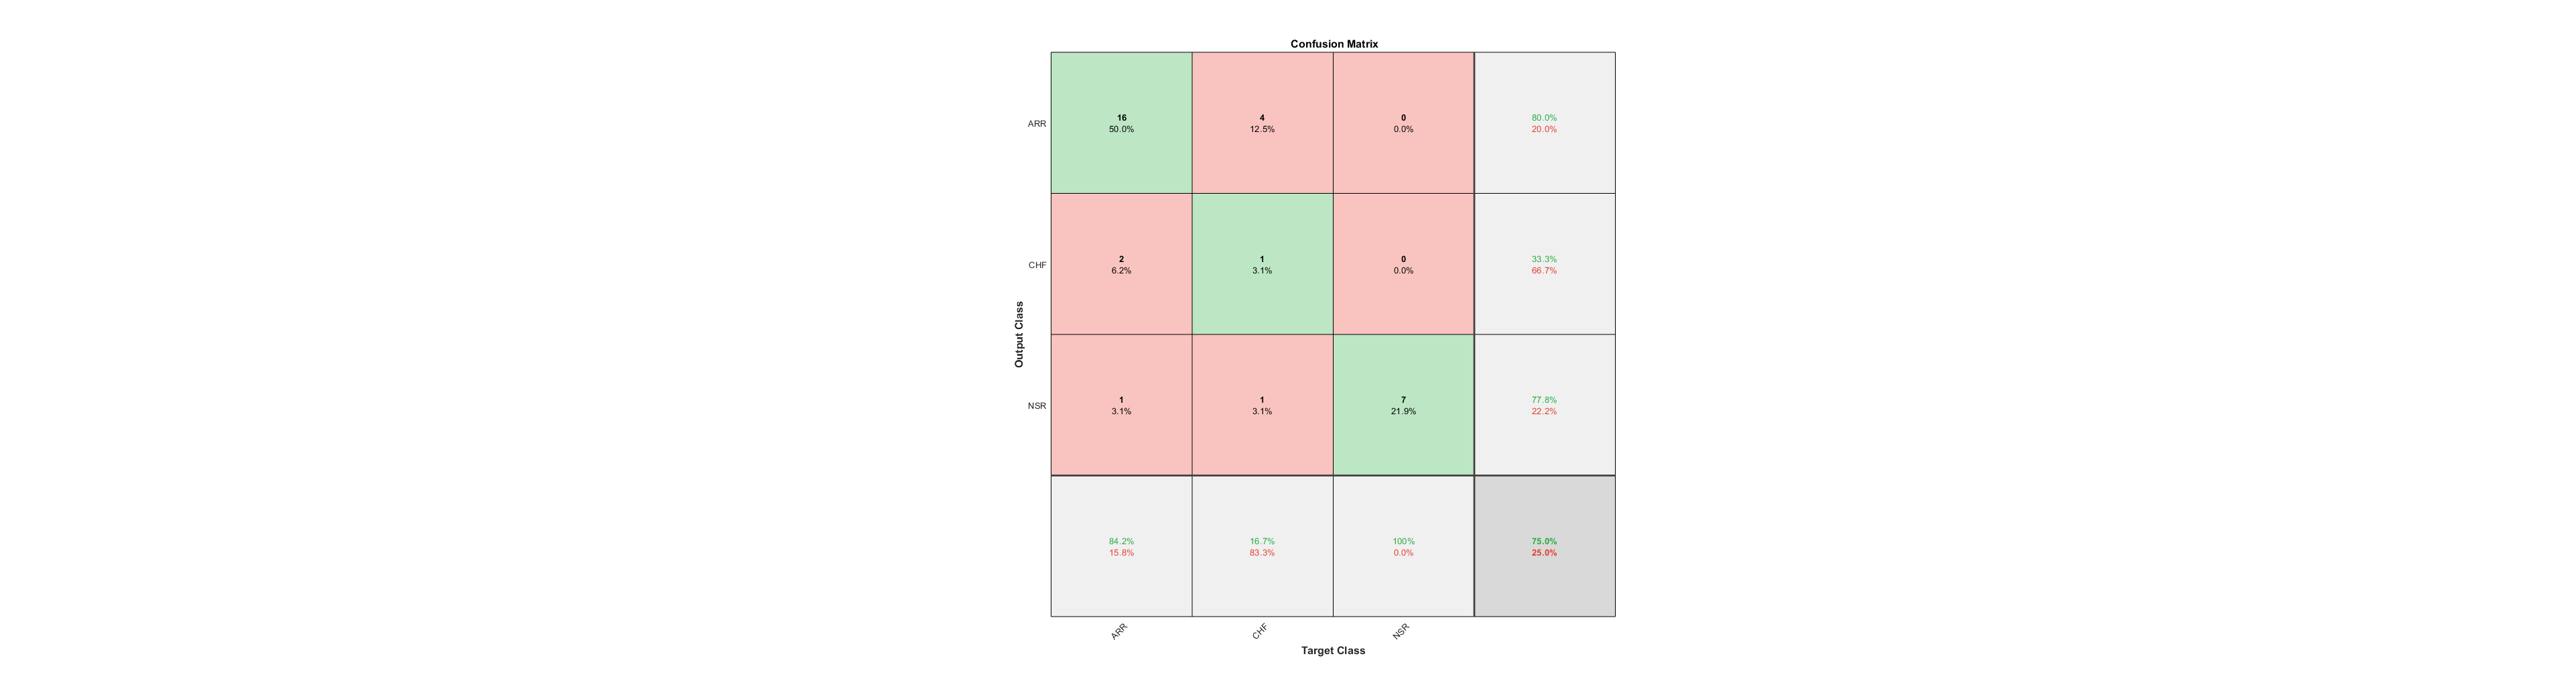

NewDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');

SqueezeNetLayerGraph = replaceLayer(SqueezeNetLayerGraph,tmpLayer.Name,NewDropoutLayer);

 As was done with GoogLeNet, increase the learning rate factors of the new layer.

NumClasses = numel(categories(TrainingImages.Labels));
tmpLayer = SqueezeNetLayerGraph.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,NumClasses, ...

AlexNet Accuracy: 87.5%


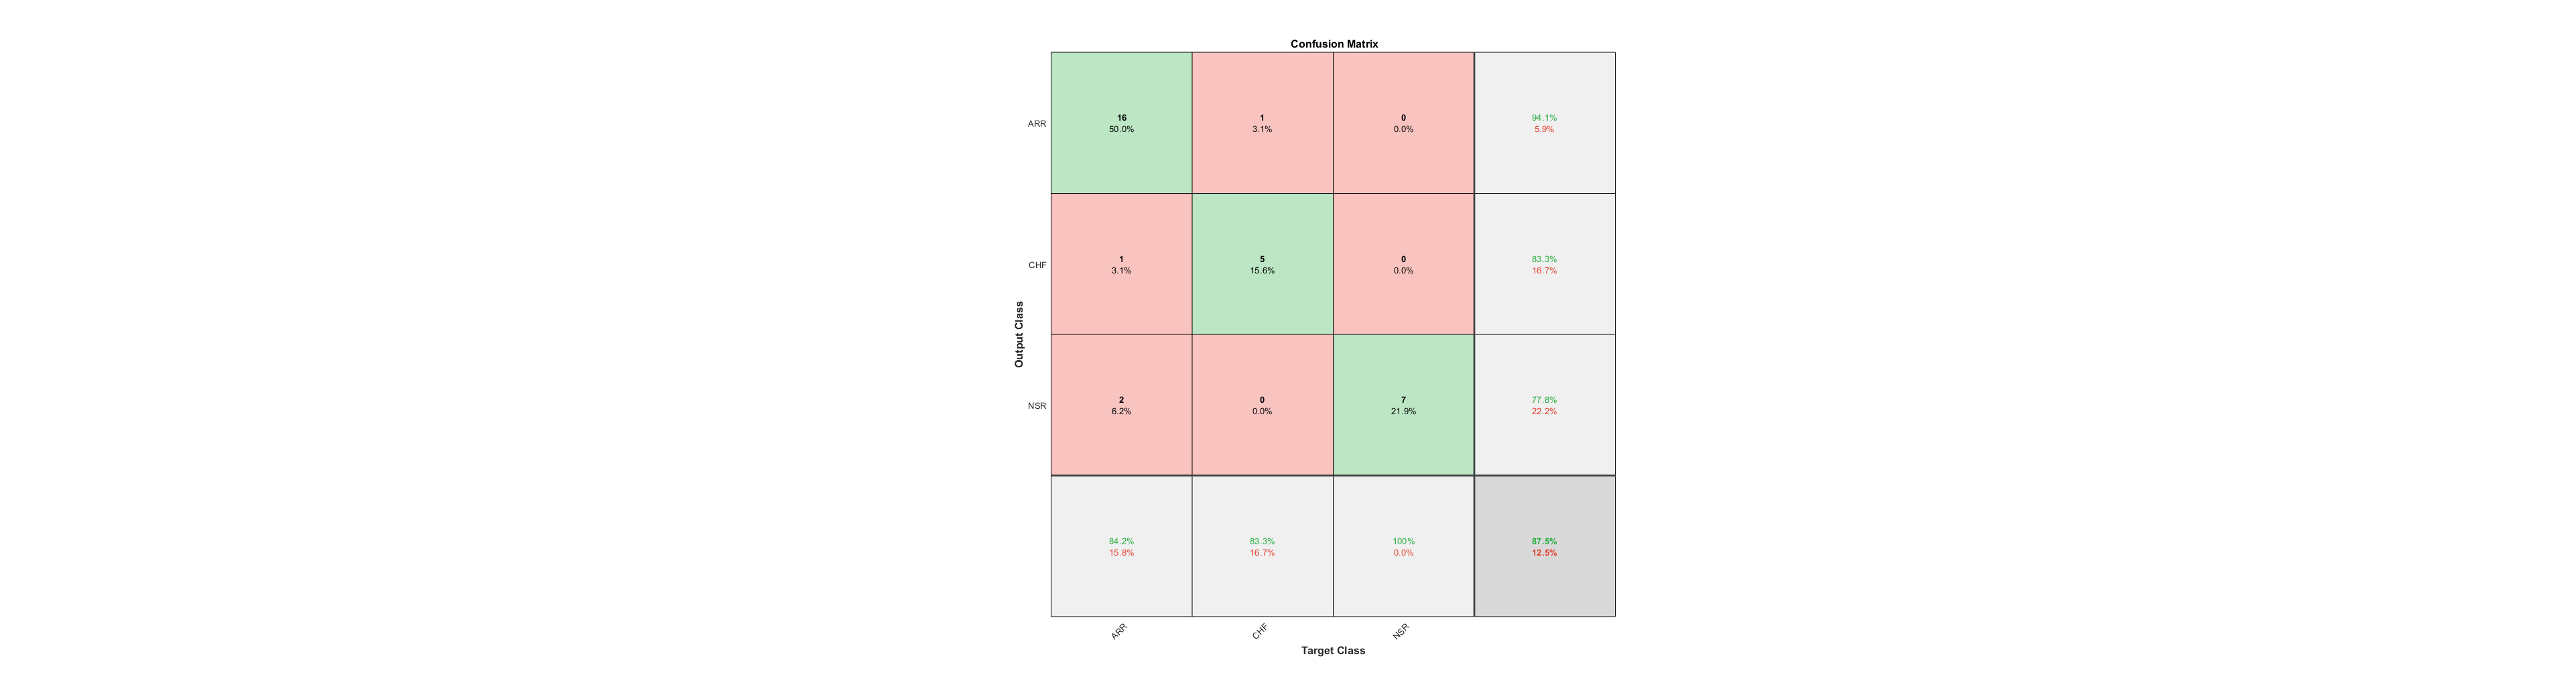

        'Name','new_conv', ...

        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
SqueezeNetLayerGraph = replaceLayer(SqueezeNetLayerGraph,tmpLayer.Name,newLearnableLayer);

Error using imageDatastore (line 139)
Cannot find files or folders matching: 'ECG_To_Evaluate.jpg'.

Replace the classification layer with a new one without class labels.

tmpLayer = SqueezeNetLayerGraph.Layers(end);
NewClassLayer = classificationLayer('Name','new_classoutput');
SqueezeNetLayerGraph = replaceLayer(SqueezeNetLayerGraph,tmpLayer.Name,NewClassLayer);

Inspect the last six layers of the network.

SqueezeNetLayerGraph.Layers(63:68)

**Set Training Options and Train SqueezeNet**

MiniBatchSize = 10;  % Batch size
valFreq = floor(numel(RescaledTrainingImages.Files)/MiniBatchSize);
SqueezeNetOptions = trainingOptions('sgdm',...
    'MiniBatchSize',MiniBatchSize,...
    'MaxEpochs',15,...
    'InitialLearnRate',3e-4,...
    'ValidationData',RescaledValidationImages,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

### AlexNet

Importing pre-trained AlexNet

AlexNet = alexnet;  
TransferLayers = AlexNet.Layers(1:end-3);

** Number of output classes, i.e. ARR, CHF, and NSR**

NumClasses = 3; 


**Defining layers of alexnet**

AlexNetLayerGraph = [TransferLayers
    fullyConnectedLayer(NumClasses, 'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
    softmaxLayer
    classificationLayer];


**Training options**

MiniBatchSize = 10;  % Batch size
valFreq = floor(numel(RescaledTrainingImages.Files)/MiniBatchSize);
AlexNetOptions = trainingOptions('sgdm', ...
    'MiniBatchSize', MiniBatchSize, ...
    'MaxEpochs', 20, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', RescaledValidationImages, ...
    'ValidationFrequency', valFreq, ...
    'Verbose', 1, ...
    'Plots', 'training-progress');

## Train the Networks

TrainModel = 1;  % 1: Train a new model, 0: Load trained models
    
if TrainModel == 0  % Load previous trainings

    load('GoogLeNetModel.mat');   % Load trained model
    load('SqueezeNetModel.mat');  % Load trained model
    load('AlexNetModel.mat');     % Load trained model
else
    rng default

 **Training the GoogLeNet**

    GoogLeNetTrained = trainNetwork(TrainingImages,GoogLeNetLayerGraph,GoogLeNetOptions);
    GoogLeNetTrained.Layers(end)
    save('GoogLeNetModel2.mat','GoogLeNetTrained')  % Save the trained model

** Training the SqueezeNet**

    SqueezeNetTrained = trainNetwork(RescaledTrainingImages,SqueezeNetLayerGraph,SqueezeNetOptions);
    SqueezeNetTrained.Layers(end)
    save('SqueezeNetModel2.mat','SqueezeNetTrained')  % Save the trained model

** Training the AlexNet**

    AlexNetTrained = trainNetwork(RescaledTrainingImages, AlexNetLayerGraph, AlexNetOptions);
    AlexNetTrained.Layers(end)
    save('AlexNetModel2.mat','AlexNetTrained')  % Save the trained model
end

## Test and validate the Networks -- Confusion Charts

Compare the results and the reliabilty of the different Time and Frequency Representations and the different Networks. Explain the differences!

** Classify ECGs using GoogLeNet**

[PredictedLabel, ~] = classify(GoogLeNetTrained,ValidationImages);
Accuracy = mean(PredictedLabel==ValidationImages.Labels);
disp(['GoogLeNet Accuracy: ' num2str(100*Accuracy) '%'])
plotconfusion(ValidationImages.Labels, PredictedLabel)  % Plot confusion chart

**Classify ECGs using SqueezeNet**

[PredictedLabel, ~] = classify(SqueezeNetTrained,RescaledValidationImages);
Accuracy = mean(PredictedLabel==ValidationImages.Labels);
disp(['SqueezeNet Accuracy: ' num2str(100*Accuracy) '%'])
plotconfusion(ValidationImages.Labels, PredictedLabel)  % Plot confusion chart

**Classify ECGs using AlexNet**

[PredictedLabel, ~] = classify(AlexNetTrained, RescaledValidationImages);
Accuracy = mean(PredictedLabel==ValidationImages.Labels);
disp(['AlexNet Accuracy: ' num2str(100*Accuracy) '%'])
plotconfusion(ValidationImages.Labels, PredictedLabel)  % Plot confusion chart

## Apply the Networks to given ECG Signal

Classification of the given ECG signal

ECGImage = imageDatastore('ECG_To_Evaluate.jpg');         % Load the generated image for the given ECG

ECGImage2 = augmentedImageDatastore([227 227],ECGImage);  % Resize the ECG scalogram for AlexNet and SqueezNet compitability

disp('--- ECG Signal Classification ---')

**Classify using GoogLeNet**

[Prediction,Probability] = classify(GoogLeNetTrained,ECGImage);  
disp(['GoogLeNet -> ECG Type: ' char(Prediction) ', Probability: ' num2str(100*max(Probability)) '%'])

** Classify using SqueezNet**

[Prediction,Probability] = classify(SqueezeNetTrained,ECGImage2); 
disp(['SqueezeNet -> ECG Type: ' char(Prediction) ', Probability: ' num2str(100*max(Probability)) '%'])

** Classify using AlexNet**

[Prediction,Probability] = classify(AlexNetTrained,ECGImage2); 
disp(['AlexNet -> ECG Type: ' char(Prediction) ', Probability: ' num2str(100*max(Probability)) '%'])